# Time lapsed tSNE plots of syllables

### Choose settings

% Query for syllables to be retrieved
birdname = 'br177yw112';
syls = ['all'];
days = [62,661,73,86];

% set spectogram parameters
min_max_duration = [20 150]; % select syls only with this max duration
overlap_windowsize = [0.9 10]; %pct overlap, bin size (msec)
numWindows = calcNumWindows(min_max_duration(1),overlap_windowsize); % # of windows of shortest syllable

Number of time bins: 11


whichWindows = [1 numWindows];%['end-' num2str(numWindows) '_to_end'];
params = struct("overlap_windowsize",overlap_windowsize,"numWindows",numWindows,"whichWindows",whichWindows,...
    "min_max_duration",min_max_duration);

### Compile the spectrogram matrices for syllable trials

spect_params = struct with fields:
    overlap_windowsize: [0.9000 10]
            numWindows: 11
          whichWindows: [1 11]
      min_max_duration: [20 150]


day = 62

min_win_length = 15

max_win_length = 161

ind_min = 894

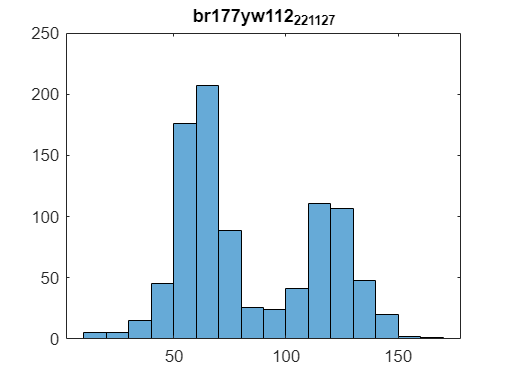

syl_min_win = '-'

day = 661

min_win_length = 25

max_win_length = 163

ind_min =     97
   707


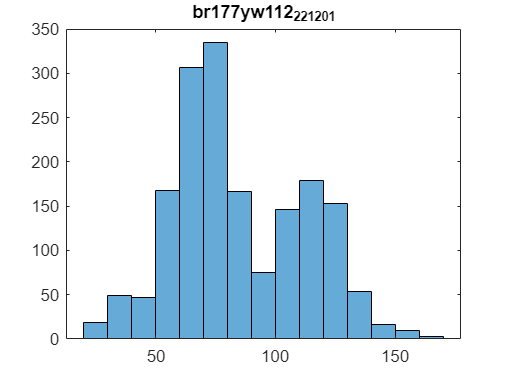

syl_min_win = '00'

day = 73

min_win_length = 14

max_win_length = 161

ind_min =         1115
        1129
        1283
        1623
        1764
        1805
        1812
        2419
        2920
        4565


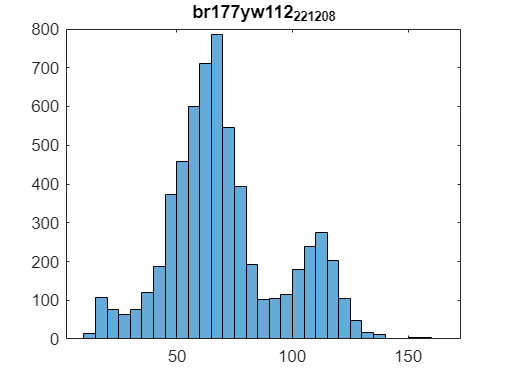

syl_min_win = '00000000000-0--'

day = 86

min_win_length = 26

max_win_length = 162

ind_min =         1582
        1979
        3797
        5699
        5801
        6394
        6626
        6677


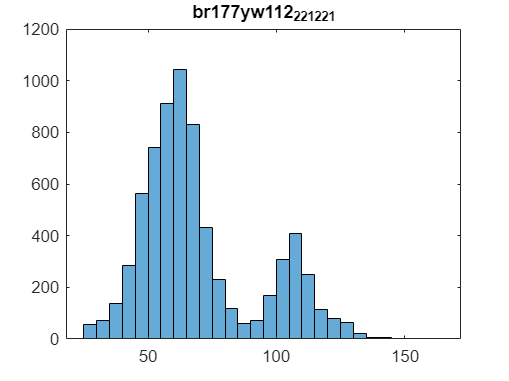

syl_min_win = '0sq0qq--'

% directory where compiled data will be saved
savedir = "C:\Users\LPASCU2\OneDrive - Emory University\MATLAB_CODE\ephys-songbird\data\processed\tSNE_syllable_spects";
[spects_all_cut,labels_all,days_all] = compileSylSpects(birdname,syls,days,savedir,params);

## Compile the matrix for feeding to tsne

%% Create a spectrogram matrix of all trials padding with zero trials that are less than the maximum syllable duration
filename = 'spectrograms_br177yw112_syls_all_days_62_66_73_86_syldur_1_to_11.mat';
load(filename,'spect_uncut')
spects_all_zero_padded = spectsZeroPad(spect_uncut);
save(filename,"spects_all_zero_padded", '-append');

## Apply t-SNE with 3 dimensions

% Step 3: Prepare Data for t-SNE 
filename = 'spectrograms_br177yw112_syls_all_days_62_66_73_86_syldur_1_to_11.mat';
load(filename,'spects_all_zero_padded')

featureMatrix = spects_all_zero_padded; % spects_all or spects_all_zero_padded
perp = 120;
exg = 5;

% Step 4: Apply t-SNE with 3 dimensions
rng(42); % Set random seed for reproducibility
[tsneResult,loss] = tsne(featureMatrix, 'NumDimensions', 3,'Perplexity',perp,'Exaggeration',exg);
disp(loss)

% Save to existing file
save(filename,'tsneResult_zeroPadded_perp_120_exg_5','-append')

## Plot t-SNE results in static 3D plot

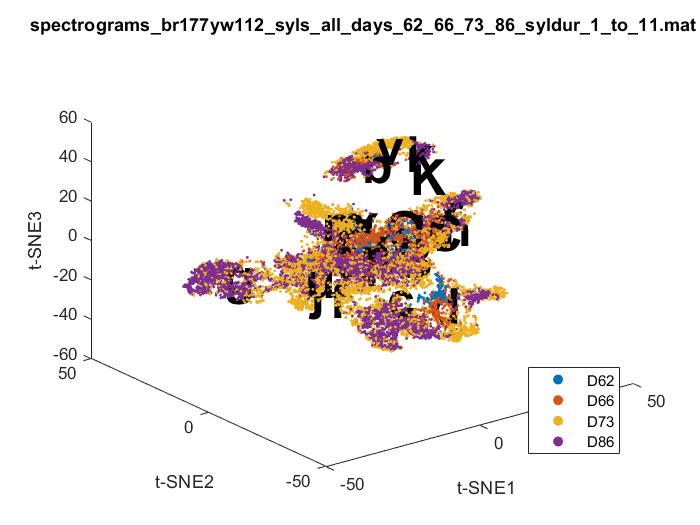

% Step 5: Assign unique colors based labels
plotLabel = days_all; % assign which labels for coloring and grouping

% Step 5b: Optional - assign unique colors based on second label
plotLabel2 = labels_all; % assign which labels for coloring and grouping
  
% Create 3D scatter plot
tsneResult = tsneResult_zeroPadded_perp_120_exg_5; 
plot3Dtsne(tsneResult,plotLabel,plotLabel2)
title(filename,'Interpreter','latex')


% Save figure
savefig(gcf,[filename(1:end-4) '_zeropadded_perp_120_exg_5.fig'])

## Create video of tSNE results plotted through a sliding window

% Define the tSNE on the whole dataset
tsneResultAll = tsneResult;

% Fix the xyz axes based on the max values of the tsne results
ax_mins = [min(tsneResultAll(:, 1)), min(tsneResultAll(:, 2)), min(tsneResultAll(:, 3))];
ax_maxes = [max(tsneResultAll(:, 1)), max(tsneResultAll(:, 2)), max(tsneResultAll(:, 3))];

% Define parameters
bin_width = 1000;
bin_step = 50;

% Create a VideoWriter object
video_filename = [filename(1:end-4), '_MOVIE_bw' num2str(bin_width) '_step' num2str(bin_step) '.avi'];
video_writer = VideoWriter(video_filename);

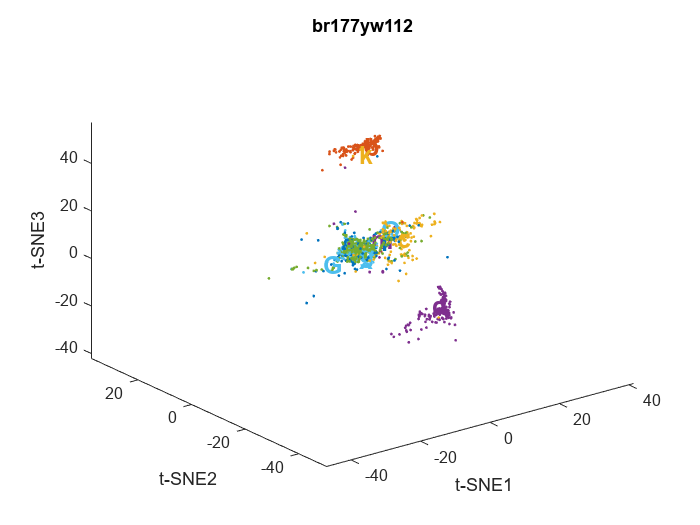

video_writer.FrameRate = 5;
open(video_writer);

% Extract the base name for the directory
[folderPath, baseFileName, ~] = fileparts(video_filename);
newDir = fullfile(folderPath, baseFileName);
if ~exist(newDir)
    mkdir(newDir); % Create the new directory
end

% Assign fixed colors for all labels 
% plotLabel = labels_all;
uniqueLabels = unique(labels_all);
numUniqueLabels = numel(uniqueLabels);
colors = lines(numUniqueLabels); % You can use any colormap you prefer

% Create a color map based on labels
labelColors = zeros(length(labels_all), 3);
for i = 1:numUniqueLabels
    labelColors(labels_all == uniqueLabels(i), :) = repmat(colors(i, :), sum(labels_all == uniqueLabels(i)), 1);
end


figure;

for start_row = 1:bin_step:(size(tsneResult, 1) - bin_width + 1)
    end_row = start_row + bin_width - 1;
    
    % Extract the current window and labels
    tsneResult_bin = tsneResultAll(start_row:end_row, :);
    plotLabels_bin = labels_all(start_row:end_row);
    uniqueLabels_bin = unique(plotLabels_bin);
    numUniqueLabels_bin = numel(uniqueLabels_bin);
    labelColors_bin = labelColors(start_row:end_row,:);

    % Create 3D scatter plot
    hold on;
    for i = 1:numUniqueLabels_bin
        idx = plotLabels_bin == uniqueLabels_bin(i);
        scatter3(tsneResult_bin(idx, 1), tsneResult_bin(idx, 2), tsneResult_bin(idx, 3), 3, labelColors_bin(idx, :), 'filled');
        
        % Label each cluster with the associated character
        centroid = mean(tsneResult_bin(idx, :), 1);
        text_color = labelColors_bin(find(idx, 1), :);
        text(centroid(1), centroid(2), centroid(3), uniqueLabels_bin(i), 'FontSize', 15, 'FontWeight', 'bold', 'Color', text_color);
    end
    hold off;

    % Set the axes limits
    xlim([ax_mins(1) ax_maxes(1)]);
    ylim([ax_mins(2) ax_maxes(2)]);
    zlim([ax_mins(3) ax_maxes(3)]);

    % Additional formatting
    title(['br177yw112']); % Adjust title as needed
    xlabel('t-SNE1');
    ylabel('t-SNE2');
    zlabel('t-SNE3');
    view(3); % Set the view to 3D
   

    % Pause for a short duration to create the animation effect
    pause(0.1);

    % Save the figure in .fig format only every 1000 trials
    if mod(start_row, 1000) == 1
        set(gcf,'Visible','On')
        figureFilename = fullfile(newDir, sprintf('Figure_%d.fig', start_row));
        savefig(gcf, figureFilename);
    end

    % Capture the current frame for the movie
    frame = getframe(gcf);
    writeVideo(video_writer, frame);

    % Clear the current figure for the next iteration
    clf;
end


% Close the video writer
close(video_writer);
